filename = 'Indian_pines_corrected.mat';
load('Indian_pines_corrected.mat');

matObj = matfile('Indian_pines_corrected.mat');

% Get the list of variable names
varList = who('-file', 'Indian_pines_corrected.mat');
disp(varList);

    {'indian_pines_corrected'}



[h, w, b] = size(indian_pines_corrected);
fprintf('Data dimensions: %d x %d pixels, %d bands\n', h, w, b);

Data dimensions: 145 x 145 pixels, 200 bands


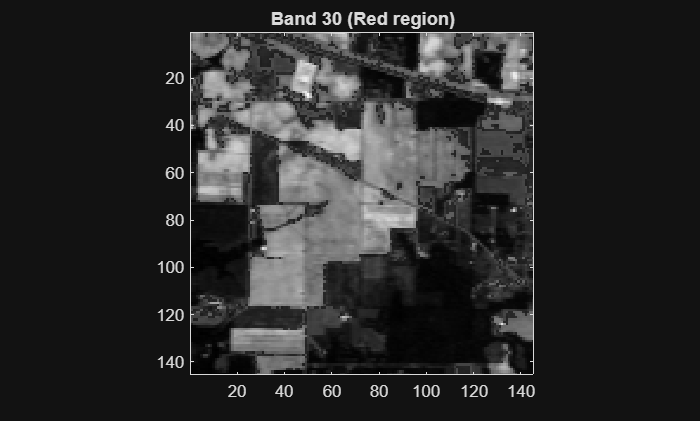


% Display one band (say band 30, which is in Red region)
figure;
imagesc(indian_pines_corrected(:,:,30));
colormap gray; axis image;
title('Band 30 (Red region)');

hCube = imhypercube(indian_pines_corrected);
disp(hCube);

  hypercube with properties:

     ImageDims: "[145x145x200 double]"
    Wavelength: [0×1 double]
      Metadata: [1×1 struct]
     BlockSize: [145 145]



dataCube = hCube

dataCube =   hypercube with properties:

     ImageDims: "[145x145x200 double]"
    Wavelength: [0×1 double]
      Metadata: [1×1 struct]
     BlockSize: [145 145]


badBands = [104:108 150:163];

%LetsTrain LSTM on simulated CNN features (PCA) and evaluate

%% Step 0: Load Indian Pines dataset
load('Indian_pines_corrected.mat');  
load('Indian_pines_gt.mat');        

[h, w, b] = size(indian_pines_corrected);
disp(['Dataset size: ', num2str(h),'x',num2str(w),'x',num2str(b)]);

Dataset size: 145x145x200



%% Step 1: Preprocess & simulate CNN features using PCA
% Reshape cube to 2D: (H*W) x Bands
X_data = reshape(indian_pines_corrected, [], b);

% Standardize
X_std = (X_data - mean(X_data,1)) ./ std(X_data,[],1);

[coeff, score, ~, ~, explained] = pca(X_std);

% Decide threshold of variance to keep
varianceToKeep = 97;  % in percent (e.g., 95 or 99)

% Find number of components that reach threshold
cumVar = cumsum(explained);
numFeatures = find(cumVar >= varianceToKeep, 1, 'first');

fprintf('Selected %d components to preserve %.2f%% variance.\n', ...
    numFeatures, cumVar(numFeatures));

Selected 17 components to preserve 97.01% variance.


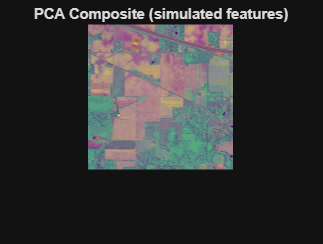


% Extract those features
cnnFeatures = score(:,1:numFeatures)';  % size: numFeatures x numPixels


%% Step 2: Prepare target labels
Y = reshape(indian_pines_gt, [], 1);  % H*W x 1

% Remove unlabeled pixels
validIdx = Y ~= 0;
cnnFeatures = cnnFeatures(:, validIdx);
Y = Y(validIdx);

%% Visualize PCA result (first 3 components)
pcImage = reshape(score(:,1:3), [h, w, 3]);  % reshape back to spatial size

figure;
imshow(rescale(pcImage)); 
title('PCA Composite (simulated features)');

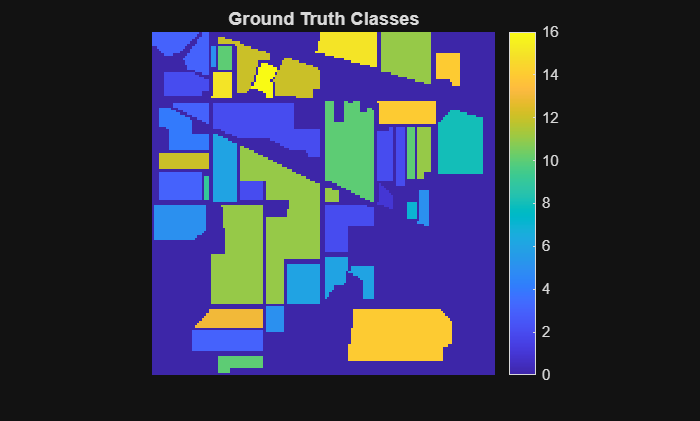

%% Ground truth labels
figure;
imagesc(indian_pines_gt);
axis image off;
title('Ground Truth Classes');
colorbar;


%% Save PCA features and labels
%% Step 4: Save to .mat
cnnData.features   = cnnFeatures;   % [numFeatures × numSamples]
cnnData.labels     = Y;             % [numSamples × 1]
cnnData.coeff      = coeff(:,1:numFeatures); % PCA projection matrix
cnnData.variance   = cumVar(numFeatures);    % variance retained
cnnData.imageSize  = [h, w, b];     % original cube shape

save('IndianPines_PCA_Features.mat', 'cnnData', '-v7.3');

disp('✅ Saved PCA features + labels into IndianPines_PCA_Features.mat');

✅ Saved PCA features + labels into IndianPines_PCA_Features.mat
